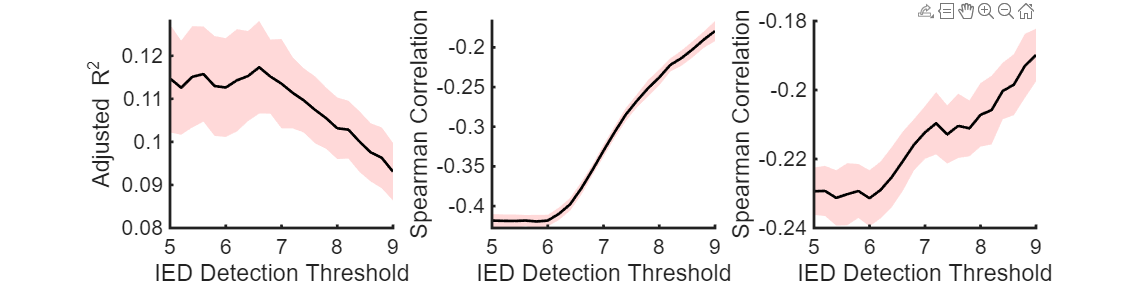

clc; clear; close all; addpath z_toolbox;
path = 'step3_IEDtw_polyfit_diffTD';
TDstr = {'5d0', '5d2', '5d4', '5d6', '5d8', '6d0', '6d2', '6d4', '6d6', '6d8', ...
        '7d0', '7d2', '7d4', '7d6', '7d8', '8d0', '8d2', '8d4', '8d6', '8d8', '9d0'};
TD = 5:0.2:9;
for nTD = 1:length(TD)
    load(fullfile(path, ['IEDtw_meth-none_TD-', TDstr{nTD}, '_polyfit.mat']), 'adjR2_twDED_as');
    A = adjR2_twDED_as(:, 6); 
    Vmean1(nTD) = mean(A(:), 'omitnan'); 
    Vstd1(nTD) = std(A(:), 'omitnan');
    load(fullfile(path, ['IEDtw_meth-none_TD-', TDstr{nTD}, '_polyfit.mat']), 'R_twDR_as');
    Vmean2(nTD) = mean(R_twDR_as, 'omitnan'); 
    Vstd2(nTD) = std(R_twDR_as, 'omitnan');
    load(fullfile(path, ['IEDtw_meth-none_TD-', TDstr{nTD}, '_polyfit-fibnVSdelay.mat']), 'R_fibNtwD_as');
    Vmean3(nTD) = mean(R_fibNtwD_as, 'omitnan'); 
    Vstd3(nTD) = std(R_fibNtwD_as, 'omitnan');
end
errorShadowX = [TD, fliplr(TD)];
figure('Units', 'centimeters', 'Position', [5, 5, 40, 10]);
subplot(1, 3, 1);
errorShadowY_upper = Vmean1+Vstd1; 
errorShadowY_lower = Vmean1-Vstd1;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean1, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); 
xlabel('IED Detection Threshold'); 
ylabel("Adjusted R^2");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
subplot(1, 3, 2);
errorShadowY_upper = Vmean2 + Vstd2; errorShadowY_lower = Vmean2 - Vstd2;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean2, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); 
ylabel("Spearman Correlation"); 
xlabel('IED Detection Threshold')
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
subplot(1, 3, 3);
errorShadowY_upper = Vmean3 + Vstd3; errorShadowY_lower = Vmean3 - Vstd3;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean3, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); 
ylabel("Spearman Correlation"); 
xlabel("IED Detection Threshold");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);